## **AOMIC PIOP2 Replication Sample - Internal Cross-Validation 'Expanded NMA Model'**

Conduction of the internal-cross-validation of the ‘Expanded NMA Model’ that is built using 6 input predictor variables (Two from each of the three task conditions). The predictor variables are derived from individual’s condition-specific coupling values and extracted by using group-based positive and group-based negative NMA masks. This script contains three parts: **Part 1** partitions the sample into five different folds (considering intelligence distribution) and creates positive and negative NMAs for each training fold and test fold. **Part 2 **uses the NMAs created in part 1 to build multiple linear regression models that are then tested for their ability to predict general intelligence in the test samples. **Part 3 **assesses the significance of the prediction with a permutation test.

Before running this script: 

- run all scripts in AOMIC Data Prep

**1.1. Prepare the coupling data for the working memory task **

1.1.1. Create a cell that contains for each subject a vector of 4 predictors for each node 

for i = 1:180
    x = final_r_all_AOMIC_PIOP2_wm_180{i,2};
    for j = 1:358
    Node_all_baseline_AOMIC_PIOP2_wm{i,j} = x(j,:);
    end
end

1.1.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (180*4)

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 180*4 matrix for each node)

n = size(Node_all_baseline_AOMIC_PIOP2_wm,2);
All_Nodes_complete_AOMIC_PIOP2_wm = cell(1,n);
for j = 1:n
    All_Nodes_complete_AOMIC_PIOP2_wm{j} = vertcat(Node_all_baseline_AOMIC_PIOP2_wm{:,j});
end 

**1.2. Prepare the coupling data for the emotion matching task **

1.2.1. Create a cell that contains for each subject a vector of 4 predictors for each node 

for i = 1:180
    x = final_r_all_AOMIC_PIOP2_emo_match_180{i,2};
    for j = 1:358
    Node_all_baseline_AOMIC_PIOP2_emo_match{i,j} = x(j,:);
    end
end

1.2.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (180*4)

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 180*4 matrix for each node)

n = size(Node_all_baseline_AOMIC_PIOP2_emo_match,2);
All_Nodes_complete_AOMIC_PIOP2_emo_match = cell(1,n);
for j = 1:n
    All_Nodes_complete_AOMIC_PIOP2_emo_match{j} = vertcat(Node_all_baseline_AOMIC_PIOP2_emo_match{:,j});
end 

**1.3. Prepare the coupling data for the stop signal task**

1.3.1. Create a cell that contains for each subject a vector of 4 predictors for each node 

for i = 1:180
    x = final_r_all_AOMIC_PIOP2_stop_signal_180{i,2};
    for j = 1:358
    Node_all_baseline_AOMIC_PIOP1_stop_signal{i,j} = x(j,:);
    end
end

1.3.2. Create cell that contains information from all subjects and all coupling measures for all nodes separetely (180*4)

% extract for each collumn 4 rows from each row and put them together in a matrix (--> I need 180*4 matrix for each node)

n = size(Node_all_baseline_AOMIC_PIOP1_stop_signal,2);
All_Nodes_complete_AOMIC_PIOP2_stop_signal = cell(1,n);
for j = 1:n
    All_Nodes_complete_AOMIC_PIOP2_stop_signal{j} = vertcat(Node_all_baseline_AOMIC_PIOP1_stop_signal{:,j});
end 

**2.  Split sample into 5 folds **

2.1. Create a loop to do the partition 100 times 

for cross_validation_round = 1:100
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

2.2. Create a CV partition based on IQ

Intelligence = AOMIC_PIOP2_behavioral_180.raven_score;


Intelligence_for_cv_partition_1 = rescale(Intelligence,1,30);
Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

2.3. Create output: indices for the families

% Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));

% Train 2 & Test 2 
index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

% Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

% Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

% Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));


2.4. Divide data in test and training samples 

2.4.1.1.  Divide the coupling data into 5 training and 5 test samples: **Working Memory**

for i = 1:358
   all_data_node = All_Nodes_complete_AOMIC_PIOP2_wm{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1,:);
   Node_test_sample_1 = all_data_node(index_test_1,:);
   
   Node_training_sample_2 = all_data_node(index_train_2,:);
   Node_test_sample_2 = all_data_node(index_test_2,:);
   
   Node_training_sample_3 = all_data_node(index_train_3,:);
   Node_test_sample_3 = all_data_node(index_test_3, :);
   
   Node_training_sample_4 = all_data_node(index_train_4,:);
   Node_test_sample_4 = all_data_node(index_test_4,:);
   
   Node_training_sample_5 = all_data_node(index_train_5,:);
   Node_test_sample_5 = all_data_node(index_test_5, :);
   
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{10,i} = Node_test_sample_5;
   
end

2.4.1.2.  Divide the coupling data into 5 training and 5 test samples: **Emotion Matching**

for i = 1:358
   all_data_node = All_Nodes_complete_AOMIC_PIOP2_emo_match{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1,:);
   Node_test_sample_1 = all_data_node(index_test_1,:);
   
   Node_training_sample_2 = all_data_node(index_train_2,:);
   Node_test_sample_2 = all_data_node(index_test_2,:);
   
   Node_training_sample_3 = all_data_node(index_train_3,:);
   Node_test_sample_3 = all_data_node(index_test_3, :);
   
   Node_training_sample_4 = all_data_node(index_train_4,:);
   Node_test_sample_4 = all_data_node(index_test_4,:);
   
   Node_training_sample_5 = all_data_node(index_train_5,:);
   Node_test_sample_5 = all_data_node(index_test_5, :);
   
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{10,i} = Node_test_sample_5;
   
end

2.4.1.3. Divide the coupling data into 5 training and 5 test samples: **Stop Signal**

for i = 1:358
   all_data_node = All_Nodes_complete_AOMIC_PIOP2_stop_signal{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1,:);
   Node_test_sample_1 = all_data_node(index_test_1,:);
   
   Node_training_sample_2 = all_data_node(index_train_2,:);
   Node_test_sample_2 = all_data_node(index_test_2,:);
   
   Node_training_sample_3 = all_data_node(index_train_3,:);
   Node_test_sample_3 = all_data_node(index_test_3, :);
   
   Node_training_sample_4 = all_data_node(index_train_4,:);
   Node_test_sample_4 = all_data_node(index_test_4,:);
   
   Node_training_sample_5 = all_data_node(index_train_5,:);
   Node_test_sample_5 = all_data_node(index_test_5, :);
   
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{10,i} = Node_test_sample_5;
   
end

2.4.2. Divide intelligence into 5 training samples & 5 test samples

Intelligence = AOMIC_PIOP2_behavioral_180.raven_score;

Intelligence_train_1 = Intelligence(index_train_1,:);
Intelligence_train_2 = Intelligence(index_train_2,:);
Intelligence_train_3 = Intelligence(index_train_3,:);
Intelligence_train_4 = Intelligence(index_train_4,:);
Intelligence_train_5 = Intelligence(index_train_5,:);

Intelligence_test_1 = Intelligence(index_test_1,:);
Intelligence_test_2 = Intelligence(index_test_2,:);
Intelligence_test_3 = Intelligence(index_test_3,:);
Intelligence_test_4 = Intelligence(index_test_4,:);
Intelligence_test_5 = Intelligence(index_test_5,:);

Intelligence_training_samples{1,:} = Intelligence_train_1;
Intelligence_training_samples{2,:} = Intelligence_train_2;
Intelligence_training_samples{3,:} = Intelligence_train_3;
Intelligence_training_samples{4,:} = Intelligence_train_4;
Intelligence_training_samples{5,:} = Intelligence_train_5;

Intelligence_test_samples{1,:} = Intelligence_test_1;
Intelligence_test_samples{2,:} = Intelligence_test_2;
Intelligence_test_samples{3,:} = Intelligence_test_3;
Intelligence_test_samples{4,:} = Intelligence_test_4;
Intelligence_test_samples{5,:} = Intelligence_test_5;

2.4.3.  Divide Confounding variables into 5 training samples & 5 test samples

Age = AOMIC_PIOP2_behavioral_180.age;

Age_train_1 = Age(index_train_1,:);
Age_train_2 = Age(index_train_2,:);
Age_train_3 = Age(index_train_3,:);
Age_train_4 = Age(index_train_4,:);
Age_train_5 = Age(index_train_5,:);

Age_test_1 = Age(index_test_1,:);
Age_test_2 = Age(index_test_2,:);
Age_test_3 = Age(index_test_3,:);
Age_test_4 = Age(index_test_4,:);
Age_test_5 = Age(index_test_5, :);


Age_training_samples{1,:} = Age_train_1;
Age_training_samples{2,:} = Age_train_2;
Age_training_samples{3,:} = Age_train_3;
Age_training_samples{4,:} = Age_train_4;
Age_training_samples{5,:} = Age_train_5;

Age_test_samples{1,:} = Age_test_1;
Age_test_samples{2,:} = Age_test_2;
Age_test_samples{3,:} = Age_test_3;
Age_test_samples{4,:} = Age_test_4;
Age_test_samples{5,:} = Age_test_5;

Gender = AOMIC_PIOP2_behavioral_180.sex_num;

Gender_train_1 = Gender(index_train_1,:);
Gender_train_2 = Gender(index_train_2,:);
Gender_train_3 = Gender(index_train_3,:);
Gender_train_4 = Gender(index_train_4,:);
Gender_train_5 = Gender(index_train_5,:);

Gender_test_1 = Gender(index_test_1,:);
Gender_test_2 = Gender(index_test_2,:);
Gender_test_3 = Gender(index_test_3,:);
Gender_test_4 = Gender(index_test_4,:);
Gender_test_5 = Gender(index_test_5,:);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

Gender_test_samples{1,:} = Gender_test_1;
Gender_test_samples{2,:} = Gender_test_2;
Gender_test_samples{3,:} = Gender_test_3;
Gender_test_samples{4,:} = Gender_test_4;
Gender_test_samples{5,:} = Gender_test_5;

meanFDJenk_wm = AOMIC_PIOP2_behavioral_180.("MeanFD wm");

meanFDJenk_wm_train_1 = meanFDJenk_wm(index_train_1,:);
meanFDJenk_wm_train_2 = meanFDJenk_wm(index_train_2,:);
meanFDJenk_wm_train_3 = meanFDJenk_wm(index_train_3,:);
meanFDJenk_wm_train_4 = meanFDJenk_wm(index_train_4,:);
meanFDJenk_wm_train_5 = meanFDJenk_wm(index_train_5,:);

meanFDJenk_wm_test_1 = meanFDJenk_wm(index_test_1,:);
meanFDJenk_wm_test_2 = meanFDJenk_wm(index_test_2,:);
meanFDJenk_wm_test_3 = meanFDJenk_wm(index_test_3, :);
meanFDJenk_wm_test_4 = meanFDJenk_wm(index_test_4,:);
meanFDJenk_wm_test_5 = meanFDJenk_wm(index_test_5, :);


meanFDJenk_wm_training_samples{1,:} = meanFDJenk_wm_train_1;
meanFDJenk_wm_training_samples{2,:} = meanFDJenk_wm_train_2;
meanFDJenk_wm_training_samples{3,:} = meanFDJenk_wm_train_3;
meanFDJenk_wm_training_samples{4,:} = meanFDJenk_wm_train_4;
meanFDJenk_wm_training_samples{5,:} = meanFDJenk_wm_train_5;

meanFDJenk_wm_test_samples{1,:} = meanFDJenk_wm_test_1;
meanFDJenk_wm_test_samples{2,:} = meanFDJenk_wm_test_2;
meanFDJenk_wm_test_samples{3,:} = meanFDJenk_wm_test_3;
meanFDJenk_wm_test_samples{4,:} = meanFDJenk_wm_test_4;
meanFDJenk_wm_test_samples{5,:} = meanFDJenk_wm_test_5;

meanFDJenk_emo_match = AOMIC_PIOP2_behavioral_180.("MeanFD emo match");

meanFDJenk_emo_match_train_1 = meanFDJenk_emo_match(index_train_1,:);
meanFDJenk_emo_match_train_2 = meanFDJenk_emo_match(index_train_2,:);
meanFDJenk_emo_match_train_3 = meanFDJenk_emo_match(index_train_3,:);
meanFDJenk_emo_match_train_4 = meanFDJenk_emo_match(index_train_4,:);
meanFDJenk_emo_match_train_5 = meanFDJenk_emo_match(index_train_5,:);

meanFDJenk_emo_match_test_1 = meanFDJenk_emo_match(index_test_1,:);
meanFDJenk_emo_match_test_2 = meanFDJenk_emo_match(index_test_2,:);
meanFDJenk_emo_match_test_3 = meanFDJenk_emo_match(index_test_3, :);
meanFDJenk_emo_match_test_4 = meanFDJenk_emo_match(index_test_4,:);
meanFDJenk_emo_match_test_5 = meanFDJenk_emo_match(index_test_5, :);


meanFDJenk_emo_match_training_samples{1,:} = meanFDJenk_emo_match_train_1;
meanFDJenk_emo_match_training_samples{2,:} = meanFDJenk_emo_match_train_2;
meanFDJenk_emo_match_training_samples{3,:} = meanFDJenk_emo_match_train_3;
meanFDJenk_emo_match_training_samples{4,:} = meanFDJenk_emo_match_train_4;
meanFDJenk_emo_match_training_samples{5,:} = meanFDJenk_emo_match_train_5;

meanFDJenk_emo_match_test_samples{1,:} = meanFDJenk_emo_match_test_1;
meanFDJenk_emo_match_test_samples{2,:} = meanFDJenk_emo_match_test_2;
meanFDJenk_emo_match_test_samples{3,:} = meanFDJenk_emo_match_test_3;
meanFDJenk_emo_match_test_samples{4,:} = meanFDJenk_emo_match_test_4;
meanFDJenk_emo_match_test_samples{5,:} = meanFDJenk_emo_match_test_5;

meanFDJenk_stop_signal = AOMIC_PIOP2_behavioral_180.("MeanFD stop signal");

meanFDJenk_stop_signal_1 = meanFDJenk_stop_signal(index_train_1,:);
meanFDJenk_stop_signal_2 = meanFDJenk_stop_signal(index_train_2,:);
meanFDJenk_stop_signal_3 = meanFDJenk_stop_signal(index_train_3,:);
meanFDJenk_stop_signal_4 = meanFDJenk_stop_signal(index_train_4,:);
meanFDJenk_stop_signal_5 = meanFDJenk_stop_signal(index_train_5,:);

meanFDJenk_stop_signal_test_1 = meanFDJenk_stop_signal(index_test_1,:);
meanFDJenk_stop_signal_test_2 = meanFDJenk_stop_signal(index_test_2,:);
meanFDJenk_stop_signal_test_3 = meanFDJenk_stop_signal(index_test_3,:);
meanFDJenk_stop_signal_test_4 = meanFDJenk_stop_signal(index_test_4,:);
meanFDJenk_stop_signal_test_5 = meanFDJenk_stop_signal(index_test_5,:);


meanFDJenk_stop_signal_training_samples{1,:} = meanFDJenk_stop_signal_1;
meanFDJenk_stop_signal_training_samples{2,:} = meanFDJenk_stop_signal_2;
meanFDJenk_stop_signal_training_samples{3,:} = meanFDJenk_stop_signal_3;
meanFDJenk_stop_signal_training_samples{4,:} = meanFDJenk_stop_signal_4;
meanFDJenk_stop_signal_training_samples{5,:} = meanFDJenk_stop_signal_5;

meanFDJenk_stop_signal_test_samples{1,:} = meanFDJenk_stop_signal_test_1;
meanFDJenk_stop_signal_test_samples{2,:} = meanFDJenk_stop_signal_test_2;
meanFDJenk_stop_signal_test_samples{3,:} = meanFDJenk_stop_signal_test_3;
meanFDJenk_stop_signal_test_samples{4,:} = meanFDJenk_stop_signal_test_4;
meanFDJenk_stop_signal_test_samples{5,:} = meanFDJenk_stop_signal_test_5;

LQ = AOMIC_PIOP2_behavioral_180.handedness_num;

LQ_train_1 = LQ(index_train_1,:);
LQ_train_2 = LQ(index_train_2,:);
LQ_train_3 = LQ(index_train_3,:);
LQ_train_4 = LQ(index_train_4,:);
LQ_train_5 = LQ(index_train_5,:);

LQ_test_1 = LQ(index_test_1,:);
LQ_test_2 = LQ(index_test_2,:);
LQ_test_3 = LQ(index_test_3,:);
LQ_test_4 = LQ(index_test_4,:);
LQ_test_5 = LQ(index_test_5,:);


LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

LQ_test_samples{1,:} = LQ_test_1;
LQ_test_samples{2,:} = LQ_test_2;
LQ_test_samples{3,:} = LQ_test_3;
LQ_test_samples{4,:} = LQ_test_4;
LQ_test_samples{5,:} = LQ_test_5;

**2.5. Working Memory**

2.5.1.  Build a positive and negative Node Measure Assignment (NMA) for each training sample 

2.5.1.1.  Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{fold,i};
    
     for p = 1:4 % correlate each communication measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_wm_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_wm{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_wm{fold,2} = Correlation_com_measure_fold_pval;
end

2.5.1.2. Find out which ones correlate the most positive with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_wm{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_wm{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_wm{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.5.1.3. Find out which ones correlate the most negative with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_wm{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_wm{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_wm{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.5.1.4. Define sizes of training samples and test samples 

size_training_sample_1 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{5,1},1);

size_test_sample_1 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{6,1},1);
size_test_sample_2 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{7,1},1);
size_test_sample_3 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{8,1},1);
size_test_sample_4 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{9,1},1);
size_test_sample_5 = size(All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{10,1},1);

size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

size_training_test_samples{1,2} = size_test_sample_1;
size_training_test_samples{2,2} = size_test_sample_2;
size_training_test_samples{3,2} = size_test_sample_3;
size_training_test_samples{4,2} = size_test_sample_4;
size_training_test_samples{5,2} = size_test_sample_5; 

2.5.1.5.  Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_wm{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_wm{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.5.1.6. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_wm{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_wm{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.5.2. Build a positive and negative Node Measure Assignment (NMA) for each test sample

2.5.2.1.. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_wm{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_wm{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.5.2.2. Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_wm{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_PIOP2_wm{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_wm{fold,2} = Best_case_scenario_r_values_neg_test;

end

**2.6. Emotion Matching**

2.6.1.  Build a positive and negative node measure assignment (NMA) for each training sample

2.6.1.1. Build a correlation matrix for each training fold 

for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{fold,i};
    
     for p = 1:4 % correlate each communication measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_emo_match_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_emo_match{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_emo_match{fold,2} = Correlation_com_measure_fold_pval;
end

2.6.1.2. Find out which ones correlate the most positive with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_emo_match{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_emo_match{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_emo_match{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.6.1.3.  Find out which ones correlate the most negative with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_emo_match{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_emo_match{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_emo_match{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.6.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_emo_match{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_emo_match{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.6.1.5  Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_emo_match{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_emo_match{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.6.2. Build a positive and negative Node Measure Assignment (NMA) for each test sample

2.6.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_emo_match{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_emo_match{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.6.2.2.Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_emo_match{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_PIOP2_emo_match{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_emo_match{fold,2} = Best_case_scenario_r_values_neg_test;

end

**2.7. Stop Signal**

2.7.1. Build a positive and negative Node Measure Assignment (NMA) for each training sample

2.7.1.1. Build a correlation matrix for each training fold


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,4); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,4); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{fold,i};
    
     for p = 1:4 % correlate each communication measure with intelligence
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [Age_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_stop_signal_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds_stop_signal{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds_stop_signal{fold,2} = Correlation_com_measure_fold_pval;
end

2.7.1.2. Find out which ones correlate the most positive with intelligence score

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_stop_signal{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold_stop_signal{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold_stop_signal{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

2.7.1.3.  Find out which ones correlate the most negative with intelligence score 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds_stop_signal{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold_stop_signal{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold_stop_signal{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

2.7.1.4. Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_stop_signal{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples_stop_signal{fold,1} = Best_case_scenario_r_values_pos_train;

end 

2.7.1.5. Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_stop_signal{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples_stop_signal{fold,2} = Best_case_scenario_r_values_neg_train;

end 

2.7.2. Build a positive and negative Node Measure Assignment (NMA) for each test sample

2.7.2.1. Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold_stop_signal{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples_stop_signal{fold,1} = Best_case_scenario_r_values_pos_test;

end

2.7.2.2.  Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold_stop_signal{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_AOMIC_PIOP2_stop_signal{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples_stop_signal{fold,2} = Best_case_scenario_r_values_neg_test;

end

**Part 2:**

Use Node-Measure Assignments created above to build multiple linear regression model in training samples and test it in test samples. 

## **Part 2: Internal Cross Validation of Multiple Linear Regression**

This  is Part 2 of the Cross Validation of the Multiple Linear Regression Model. It uses the Node-Measure Assignments that were created above 

to build multiple linear regression models that are then tested in the test sample. 

**1. Build the models for the training samples **

1.1. Training Sample 1

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_wm_train_1 meanFDJenk_emo_match_train_1 meanFDJenk_stop_signal_1 LQ_train_1];

mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1);
residuals_intelligence_train_1 = mdl_regress_train_1_intelligence.Residuals.Raw;

[residuals_intelligence_train_1_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{1,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{1,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{1,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{1,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{1,2};

Take the mean per subject 

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_wm_train_1 meanFDJenk_emo_match_train_1 meanFDJenk_stop_signal_1 LQ_train_1];

mdl_regress_train_1_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_1 = mdl_regress_train_1_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_1_z, c_pos_NMA_wm_train_1, s_pos_NMA_wm_train_1] = normalize(residuals_wm_pos_train_1);

mdl_regress_train_1_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_1 = mdl_regress_train_1_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_1_z, c_neg_NMA_wm_train_1, s_neg_NMA_wm_train_1] = normalize(residuals_wm_neg_train_1);

mdl_regress_train_1_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_1 = mdl_regress_train_1_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_1_z, c_pos_NMA_emo_match_train_1, s_pos_NMA_emo_match_train_1] = normalize(residuals_emo_match_pos_train_1);

mdl_regress_train_1_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_1 = mdl_regress_train_1_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_1_z, c_neg_NMA_emo_match_train_1, s_neg_NMA_emo_match_train_1] = normalize(residuals_emo_match_neg_train_1);

mdl_regress_train_1_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_1 = mdl_regress_train_1_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_1_z, c_pos_NMA_stop_signal_train_1, s_pos_NMA_stop_signal_train_1] = normalize(residuals_stop_signal_pos_train_1);

mdl_regress_train_1_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_1 = mdl_regress_train_1_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_1_z, c_neg_NMA_stop_signal_train_1, s_neg_NMA_stop_signal_train_1] = normalize(residuals_stop_signal_neg_train_1);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_1_z residuals_wm_neg_train_1_z residuals_emo_match_pos_train_1_z residuals_emo_match_neg_train_1_z residuals_stop_signal_pos_train_1_z residuals_stop_signal_neg_train_1_z residuals_intelligence_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_1_z', 'residuals_wm_neg_train_1_z', 'residuals_emo_match_pos_train_1_z', 'residuals_emo_match_neg_train_1_z', 'residuals_stop_signal_pos_train_1_z', 'residuals_stop_signal_neg_train_1_z', 'residuals_intelligence_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);

1.2. Training Sample 2

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_wm_train_2 meanFDJenk_emo_match_train_2 meanFDJenk_stop_signal_2 LQ_train_2];

mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2);
residuals_intelligence_train_2 = mdl_regress_train_2_intelligence.Residuals.Raw;

[residuals_intelligence_train_2_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{2,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{2,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{2,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{2,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{2,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding Variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_wm_train_2 meanFDJenk_emo_match_train_2 meanFDJenk_stop_signal_2 LQ_train_2];

mdl_regress_train_2_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_2 = mdl_regress_train_2_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_2_z, c_pos_NMA_wm_train_2, s_pos_NMA_wm_train_2] = normalize(residuals_wm_pos_train_2);

mdl_regress_train_2_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_2 = mdl_regress_train_2_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_2_z, c_neg_NMA_wm_train_2, s_neg_NMA_wm_train_2] = normalize(residuals_wm_neg_train_2);

mdl_regress_train_2_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_2 = mdl_regress_train_2_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_2_z, c_pos_NMA_emo_match_train_2, s_pos_NMA_emo_match_train_2] = normalize(residuals_emo_match_pos_train_2);

mdl_regress_train_2_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_2 = mdl_regress_train_2_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_2_z, c_neg_NMA_emo_match_train_2, s_neg_NMA_emo_match_train_2] = normalize(residuals_emo_match_neg_train_2);

mdl_regress_train_2_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_2 = mdl_regress_train_2_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_2_z, c_pos_NMA_stop_signal_train_2, s_pos_NMA_stop_signal_train_2] = normalize(residuals_stop_signal_pos_train_2);

mdl_regress_train_2_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_2 = mdl_regress_train_2_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_2_z, c_neg_NMA_stop_signal_train_2, s_neg_NMA_stop_signal_train_2] = normalize(residuals_stop_signal_neg_train_2);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_2_z residuals_wm_neg_train_2_z residuals_emo_match_pos_train_2_z residuals_emo_match_neg_train_2_z residuals_stop_signal_pos_train_2_z residuals_stop_signal_neg_train_2_z residuals_intelligence_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_2_z', 'residuals_wm_neg_train_2_z', 'residuals_emo_match_pos_train_2_z', 'residuals_emo_match_neg_train_2_z', 'residuals_stop_signal_pos_train_2_z', 'residuals_stop_signal_neg_train_2_z', 'residuals_intelligence_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

1.3. Training Sample 3

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_wm_train_3 meanFDJenk_emo_match_train_3 meanFDJenk_stop_signal_3 LQ_train_3];

mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3);
residuals_intelligence_train_3 = mdl_regress_train_3_intelligence.Residuals.Raw;

[residuals_intelligence_train_3_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{3,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{3,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{3,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{3,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{3,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_wm_train_3 meanFDJenk_emo_match_train_3 meanFDJenk_stop_signal_3 LQ_train_3];

mdl_regress_train_3_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_3 = mdl_regress_train_3_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_3_z, c_pos_NMA_wm_train_3, s_pos_NMA_wm_train_3] = normalize(residuals_wm_pos_train_3);

mdl_regress_train_3_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_3 = mdl_regress_train_3_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_3_z, c_neg_NMA_wm_train_3, s_neg_NMA_wm_train_3] = normalize(residuals_wm_neg_train_3);

mdl_regress_train_3_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_3 = mdl_regress_train_3_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_3_z, c_pos_NMA_emo_match_train_3, s_pos_NMA_emo_match_train_3] = normalize(residuals_emo_match_pos_train_3);

mdl_regress_train_3_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_3 = mdl_regress_train_3_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_3_z, c_neg_NMA_emo_match_train_3, s_neg_NMA_emo_match_train_3] = normalize(residuals_emo_match_neg_train_3);

mdl_regress_train_3_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_3 = mdl_regress_train_3_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_3_z, c_pos_NMA_stop_signal_train_3, s_pos_NMA_stop_signal_train_3] = normalize(residuals_stop_signal_pos_train_3);

mdl_regress_train_3_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_3 = mdl_regress_train_3_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_3_z, c_neg_NMA_stop_signal_train_3, s_neg_NMA_stop_signal_train_3] = normalize(residuals_stop_signal_neg_train_3);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_3_z residuals_wm_neg_train_3_z residuals_emo_match_pos_train_3_z residuals_emo_match_neg_train_3_z residuals_stop_signal_pos_train_3_z residuals_stop_signal_neg_train_3_z residuals_intelligence_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_3_z', 'residuals_wm_neg_train_3_z', 'residuals_emo_match_pos_train_3_z', 'residuals_emo_match_neg_train_3_z', 'residuals_stop_signal_pos_train_3_z', 'residuals_stop_signal_neg_train_3_z', 'residuals_intelligence_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);

1.4. Training Sample 4

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_wm_train_4 meanFDJenk_emo_match_train_4 meanFDJenk_stop_signal_4 LQ_train_4];

mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4);
residuals_intelligence_train_4 = mdl_regress_train_4_intelligence.Residuals.Raw;

[residuals_intelligence_train_4_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{4,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{4,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{4,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{4,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{4,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding Variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_wm_train_4 meanFDJenk_emo_match_train_4 meanFDJenk_stop_signal_4 LQ_train_4];

mdl_regress_train_4_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_4 = mdl_regress_train_4_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_4_z, c_pos_NMA_wm_train_4, s_pos_NMA_wm_train_4] = normalize(residuals_wm_pos_train_4);

mdl_regress_train_4_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_4 = mdl_regress_train_4_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_4_z, c_neg_NMA_wm_train_4, s_neg_NMA_wm_train_4] = normalize(residuals_wm_neg_train_4);

mdl_regress_train_4_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_4 = mdl_regress_train_4_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_4_z, c_pos_NMA_emo_match_train_4, s_pos_NMA_emo_match_train_4] = normalize(residuals_emo_match_pos_train_4);

mdl_regress_train_4_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_4 = mdl_regress_train_4_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_4_z, c_neg_NMA_emo_match_train_4, s_neg_NMA_emo_match_train_4] = normalize(residuals_emo_match_neg_train_4);

mdl_regress_train_4_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_4 = mdl_regress_train_4_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_4_z, c_pos_NMA_stop_signal_train_4, s_pos_NMA_stop_signal_train_4] = normalize(residuals_stop_signal_pos_train_4);

mdl_regress_train_4_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_4 = mdl_regress_train_4_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_4_z, c_neg_NMA_stop_signal_train_4, s_neg_NMA_stop_signal_train_4] = normalize(residuals_stop_signal_neg_train_4);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_4_z residuals_wm_neg_train_4_z residuals_emo_match_pos_train_4_z residuals_emo_match_neg_train_4_z residuals_stop_signal_pos_train_4_z residuals_stop_signal_neg_train_4_z residuals_intelligence_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_4_z', 'residuals_wm_neg_train_4_z', 'residuals_emo_match_pos_train_4_z', 'residuals_emo_match_neg_train_4_z', 'residuals_stop_signal_pos_train_4_z', 'residuals_stop_signal_neg_train_4_z', 'residuals_intelligence_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);

1.5. Training Sample 5

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_wm_train_5 meanFDJenk_emo_match_train_5 meanFDJenk_stop_signal_5 LQ_train_5];

mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5);
residuals_intelligence_train_5 = mdl_regress_train_5_intelligence.Residuals.Raw;

[residuals_intelligence_train_5_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{5,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{5,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{5,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{5,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{5,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_wm_train_5 meanFDJenk_emo_match_train_5 meanFDJenk_stop_signal_5 LQ_train_5];

mdl_regress_train_5_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_5 = mdl_regress_train_5_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_5_z, c_pos_NMA_wm_train_5, s_pos_NMA_wm_train_5] = normalize(residuals_wm_pos_train_5);

mdl_regress_train_5_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_5 = mdl_regress_train_5_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_5_z, c_neg_NMA_wm_train_5, s_neg_NMA_wm_train_5] = normalize(residuals_wm_neg_train_5);

mdl_regress_train_5_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_5 = mdl_regress_train_5_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_5_z, c_pos_NMA_emo_match_train_5, s_pos_NMA_emo_match_train_5] = normalize(residuals_emo_match_pos_train_5);

mdl_regress_train_5_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_5 = mdl_regress_train_5_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_5_z, c_neg_NMA_emo_match_train_5, s_neg_NMA_emo_match_train_5] = normalize(residuals_emo_match_neg_train_5);

mdl_regress_train_5_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_5 = mdl_regress_train_5_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_5_z, c_pos_NMA_stop_signal_train_5, s_pos_NMA_stop_signal_train_5] = normalize(residuals_stop_signal_pos_train_5);

mdl_regress_train_5_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_5 = mdl_regress_train_5_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_5_z, c_neg_NMA_stop_signal_train_5, s_neg_NMA_stop_signal_train_5] = normalize(residuals_stop_signal_neg_train_5);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_5_z residuals_wm_neg_train_5_z residuals_emo_match_pos_train_5_z residuals_emo_match_neg_train_5_z residuals_stop_signal_pos_train_5_z residuals_stop_signal_neg_train_5_z residuals_intelligence_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_5_z', 'residuals_wm_neg_train_5_z', 'residuals_emo_match_pos_train_5_z', 'residuals_emo_match_neg_train_5_z', 'residuals_stop_signal_pos_train_5_z', 'residuals_stop_signal_neg_train_5_z', 'residuals_intelligence_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2) Predict the intelligence in test samples**

2.1. Test Sample 1 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [Age_test_1 Gender_test_1 meanFDJenk_wm_test_1 meanFDJenk_emo_match_test_1 meanFDJenk_stop_signal_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1 );
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{1,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{1,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{1,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{1,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{1,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_wm_test_1 meanFDJenk_emo_match_test_1 meanFDJenk_stop_signal_test_1 LQ_test_1];


Positive_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_pos_bcs,confounds);

residuals_pos_wm_test_1 = (Positive_all_wm - Positive_all_pred_wm_test_1);
residuals_pos_wm_test_1_z = normalize(residuals_pos_wm_test_1,"center",c_pos_NMA_wm_train_1,"scale",s_pos_NMA_wm_train_1);

Negative_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_neg_bcs,confounds);

residuals_neg_wm_test_1 = (Negative_all_wm - Negative_all_pred_wm_test_1);
residuals_neg_wm_test_1_z = normalize(residuals_neg_wm_test_1,"center",c_neg_NMA_wm_train_1,"scale",s_neg_NMA_wm_train_1);


Positive_all_pred_emo_match_test_1 = predict(mdl_regress_train_1_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_1 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_1);
residuals_pos_emo_match_test_1_z = normalize(residuals_pos_emo_match_test_1,"center",c_pos_NMA_emo_match_train_1,"scale",s_pos_NMA_emo_match_train_1);

Negative_all_pred_emo_match_test_1 = predict(mdl_regress_train_1_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_1 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_1);
residuals_neg_emo_match_test_1_z = normalize(residuals_neg_emo_match_test_1,"center",c_neg_NMA_emo_match_train_1,"scale",s_neg_NMA_emo_match_train_1);


Positive_all_pred_stop_signal_test_1 = predict(mdl_regress_train_1_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_1 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_1);
residuals_pos_stop_signal_test_1_z = normalize(residuals_pos_stop_signal_test_1,"center",c_pos_NMA_stop_signal_train_1,"scale",s_pos_NMA_stop_signal_train_1);

Negative_all_pred_stop_signal_test_1 = predict(mdl_regress_train_1_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_1 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_1);
residuals_neg_stop_signal_test_1_z = normalize(residuals_neg_stop_signal_test_1,"center",c_neg_NMA_stop_signal_train_1,"scale",s_neg_NMA_stop_signal_train_1);

Xnew = [residuals_pos_wm_test_1_z residuals_neg_wm_test_1_z residuals_pos_emo_match_test_1_z residuals_neg_emo_match_test_1_z residuals_pos_stop_signal_test_1_z residuals_neg_stop_signal_test_1_z];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

2.2. Test Sample 2 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_wm_test_2 meanFDJenk_emo_match_test_2 meanFDJenk_stop_signal_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2 );
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{2,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{2,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{2,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{2,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{2,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_wm_test_2 meanFDJenk_emo_match_test_2 meanFDJenk_stop_signal_test_2 LQ_test_2];


Positive_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_pos_bcs,confounds);

residuals_pos_wm_test_2 = (Positive_all_wm - Positive_all_pred_wm_test_2);
residuals_pos_wm_test_2_z = normalize(residuals_pos_wm_test_2,"center",c_pos_NMA_wm_train_2,"scale",s_pos_NMA_wm_train_2);

Negative_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_neg_bcs,confounds);

residuals_neg_wm_test_2 = (Negative_all_wm - Negative_all_pred_wm_test_2);
residuals_neg_wm_test_2_z = normalize(residuals_neg_wm_test_2,"center",c_neg_NMA_wm_train_2,"scale",s_neg_NMA_wm_train_2);


Positive_all_pred_emo_match_test_2 = predict(mdl_regress_train_2_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_2 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_2);
residuals_pos_emo_match_test_2_z = normalize(residuals_pos_emo_match_test_2,"center",c_pos_NMA_emo_match_train_2,"scale",s_pos_NMA_emo_match_train_2);

Negative_all_pred_emo_match_test_2 = predict(mdl_regress_train_2_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_2 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_2);
residuals_neg_emo_match_test_2_z = normalize(residuals_neg_emo_match_test_2,"center",c_neg_NMA_emo_match_train_2,"scale",s_neg_NMA_emo_match_train_2);


Positive_all_pred_stop_signal_test_2 = predict(mdl_regress_train_2_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_2 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_2);
residuals_pos_stop_signal_test_2_z = normalize(residuals_pos_stop_signal_test_2,"center",c_pos_NMA_stop_signal_train_2,"scale",s_pos_NMA_stop_signal_train_2);

Negative_all_pred_stop_signal_test_2 = predict(mdl_regress_train_2_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_2 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_2);
residuals_neg_stop_signal_test_2_z = normalize(residuals_neg_stop_signal_test_2,"center",c_neg_NMA_stop_signal_train_2,"scale",s_neg_NMA_stop_signal_train_2);

Xnew = [residuals_pos_wm_test_2_z residuals_neg_wm_test_2_z residuals_pos_emo_match_test_2_z residuals_neg_emo_match_test_2_z residuals_pos_stop_signal_test_2_z residuals_neg_stop_signal_test_2_z];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

2.3. Test Sample 3 

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_wm_test_3 meanFDJenk_emo_match_test_3 meanFDJenk_stop_signal_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3 );
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{3,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{3,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{3,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{3,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{3,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_wm_test_3 meanFDJenk_emo_match_test_3 meanFDJenk_stop_signal_test_3 LQ_test_3];


Positive_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_pos_bcs,confounds);

residuals_pos_wm_test_3 = (Positive_all_wm - Positive_all_pred_wm_test_3);
residuals_pos_wm_test_3_z = normalize(residuals_pos_wm_test_3,"center",c_pos_NMA_wm_train_3,"scale",s_pos_NMA_wm_train_3);

Negative_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_neg_bcs,confounds);

residuals_neg_wm_test_3 = (Negative_all_wm - Negative_all_pred_wm_test_3);
residuals_neg_wm_test_3_z = normalize(residuals_neg_wm_test_3,"center",c_neg_NMA_wm_train_3,"scale",s_neg_NMA_wm_train_3);


Positive_all_pred_emo_match_test_3 = predict(mdl_regress_train_3_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_3 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_3);
residuals_pos_emo_match_test_3_z = normalize(residuals_pos_emo_match_test_3,"center",c_pos_NMA_emo_match_train_3,"scale",s_pos_NMA_emo_match_train_3);

Negative_all_pred_emo_match_test_3 = predict(mdl_regress_train_3_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_3 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_3);
residuals_neg_emo_match_test_3_z = normalize(residuals_neg_emo_match_test_3,"center",c_neg_NMA_emo_match_train_3,"scale",s_neg_NMA_emo_match_train_3);


Positive_all_pred_stop_signal_test_3 = predict(mdl_regress_train_3_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_3 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_3);
residuals_pos_stop_signal_test_3_z = normalize(residuals_pos_stop_signal_test_3,"center",c_pos_NMA_stop_signal_train_3,"scale",s_pos_NMA_stop_signal_train_3);

Negative_all_pred_stop_signal_test_3 = predict(mdl_regress_train_3_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_3 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_3);
residuals_neg_stop_signal_test_3_z = normalize(residuals_neg_stop_signal_test_3,"center",c_neg_NMA_stop_signal_train_3,"scale",s_neg_NMA_stop_signal_train_3);

Xnew = [residuals_pos_wm_test_3_z residuals_neg_wm_test_3_z residuals_pos_emo_match_test_3_z residuals_neg_emo_match_test_3_z residuals_pos_stop_signal_test_3_z residuals_neg_stop_signal_test_3_z];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);

[r,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

2.4. Test Sample 4 

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_wm_test_4 meanFDJenk_emo_match_test_4 meanFDJenk_stop_signal_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4 );
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{4,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{4,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{4,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{4,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{4,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_wm_test_4 meanFDJenk_emo_match_test_4 meanFDJenk_stop_signal_test_4 LQ_test_4];


Positive_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_pos_bcs,confounds);

residuals_pos_wm_test_4 = (Positive_all_wm - Positive_all_pred_wm_test_4);
residuals_pos_wm_test_4_z = normalize(residuals_pos_wm_test_4,"center",c_pos_NMA_wm_train_4,"scale",s_pos_NMA_wm_train_4);

Negative_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_neg_bcs,confounds);

residuals_neg_wm_test_4 = (Negative_all_wm - Negative_all_pred_wm_test_4);
residuals_neg_wm_test_4_z = normalize(residuals_neg_wm_test_4,"center",c_neg_NMA_wm_train_4,"scale",s_neg_NMA_wm_train_4);


Positive_all_pred_emo_match_test_4 = predict(mdl_regress_train_4_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_4 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_4);
residuals_pos_emo_match_test_4_z = normalize(residuals_pos_emo_match_test_4,"center",c_pos_NMA_emo_match_train_4,"scale",s_pos_NMA_emo_match_train_4);

Negative_all_pred_emo_match_test_4 = predict(mdl_regress_train_4_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_4 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_4);
residuals_neg_emo_match_test_4_z = normalize(residuals_neg_emo_match_test_4,"center",c_neg_NMA_emo_match_train_4,"scale",s_neg_NMA_emo_match_train_4);


Positive_all_pred_stop_signal_test_4 = predict(mdl_regress_train_4_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_4 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_4);
residuals_pos_stop_signal_test_4_z = normalize(residuals_pos_stop_signal_test_4,"center",c_pos_NMA_stop_signal_train_4,"scale",s_pos_NMA_stop_signal_train_4);

Negative_all_pred_stop_signal_test_4 = predict(mdl_regress_train_4_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_4 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_4);
residuals_neg_stop_signal_test_4_z = normalize(residuals_neg_stop_signal_test_4,"center",c_neg_NMA_stop_signal_train_4,"scale",s_neg_NMA_stop_signal_train_4);

Xnew = [residuals_pos_wm_test_4_z residuals_neg_wm_test_4_z residuals_pos_emo_match_test_4_z residuals_neg_emo_match_test_4_z residuals_pos_stop_signal_test_4_z residuals_neg_stop_signal_test_4_z];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

[r,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

2.5. Test Sample 5 

Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_wm_test_5 meanFDJenk_emo_match_test_5 meanFDJenk_stop_signal_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5 );
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{5,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{5,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{5,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{5,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{5,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_wm_test_5 meanFDJenk_emo_match_test_5 meanFDJenk_stop_signal_test_5 LQ_test_5];


Positive_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_pos_bcs,confounds);

residuals_pos_wm_test_5 = (Positive_all_wm - Positive_all_pred_wm_test_5);
residuals_pos_wm_test_5_z = normalize(residuals_pos_wm_test_5,"center",c_pos_NMA_wm_train_5,"scale",s_pos_NMA_wm_train_5);

Negative_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_neg_bcs,confounds);

residuals_neg_wm_test_5 = (Negative_all_wm - Negative_all_pred_wm_test_5);
residuals_neg_wm_test_5_z = normalize(residuals_neg_wm_test_5,"center",c_neg_NMA_wm_train_5,"scale",s_neg_NMA_wm_train_5);


Positive_all_pred_emo_match_test_5 = predict(mdl_regress_train_5_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_5 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_5);
residuals_pos_emo_match_test_5_z = normalize(residuals_pos_emo_match_test_5,"center",c_pos_NMA_emo_match_train_5,"scale",s_pos_NMA_emo_match_train_5);

Negative_all_pred_emo_match_test_5 = predict(mdl_regress_train_5_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_5 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_5);
residuals_neg_emo_match_test_5_z = normalize(residuals_neg_emo_match_test_5,"center",c_neg_NMA_emo_match_train_5,"scale",s_neg_NMA_emo_match_train_5);


Positive_all_pred_stop_signal_test_5 = predict(mdl_regress_train_5_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_5 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_5);
residuals_pos_stop_signal_test_5_z = normalize(residuals_pos_stop_signal_test_5,"center",c_pos_NMA_stop_signal_train_5,"scale",s_pos_NMA_stop_signal_train_5);

Negative_all_pred_stop_signal_test_5 = predict(mdl_regress_train_5_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_5 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_5);
residuals_neg_stop_signal_test_5_z = normalize(residuals_neg_stop_signal_test_5,"center",c_neg_NMA_stop_signal_train_5,"scale",s_neg_NMA_stop_signal_train_5);

Xnew = [residuals_pos_wm_test_5_z residuals_neg_wm_test_5_z residuals_pos_emo_match_test_5_z residuals_neg_emo_match_test_5_z residuals_pos_stop_signal_test_5_z residuals_neg_stop_signal_test_5_z];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

**3. Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_whole_sample; ypred2_whole_sample; ypred3_whole_sample; ypred4_whole_sample; ypred5_whole_sample];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho,pval] = corr(predicted_scores,actual_scores)

rho = -0.1498

pval = 0.0942

rho = -0.2329

pval = 0.0087

rho = -0.2301

pval = 0.0096

rho = 0.0085

pval = 0.9244

rho = -0.0982

pval = 0.2739

rho = -0.1738

pval = 0.0516

rho = -0.0873

pval = 0.3308

rho = -0.0679

pval = 0.4497

rho = -0.1670

pval = 0.0616

rho = -0.2402

pval = 0.0067

rho = -0.0555

pval = 0.5373

rho = -0.1417

pval = 0.1136

rho = 5.9838e-04

pval = 0.9947

rho = -0.0278

pval = 0.7571

rho = -0.0383

pval = 0.6699

rho = -0.1766

pval = 0.0480

rho = -0.1368

pval = 0.1266

rho = -0.1310

pval = 0.1438

rho = -0.0772

pval = 0.3905

rho = 0.0711

pval = 0.4287

rho = -0.1374

pval = 0.1249

rho = -0.0787

pval = 0.3808

rho = -0.0665

pval = 0.4594

rho = -0.2097

pval = 0.0185

rho = 0.0460

pval = 0.6088

rho = 0.0199

pval = 0.8248

rho = -0.1506

pval = 0.0922

rho = -0.1252

pval = 0.1626

rho = -0.0348

pval = 0.6986

rho = -0.1414

pval = 0.1142

rho = -0.1202

pval = 0.1799

rho = -0.1369

pval = 0.1263

rho = -0.1400

pval = 0.1180

rho = -0.1465

pval = 0.1017

rho = -0.0560

pval = 0.5334

rho = -0.1316

pval = 0.1418

rho = -0.1471

pval = 0.1004

rho = -0.1188

pval = 0.1853

rho = -0.0085

pval = 0.9247

rho = -0.0649

pval = 0.4705

rho = -0.0066

pval = 0.9417

rho = -0.1184

pval = 0.1868

rho = -0.2019

pval = 0.0234

rho = -0.1262

pval = 0.1592

rho = -0.0241

pval = 0.7886

rho = -0.1724

pval = 0.0536

rho = -0.1838

pval = 0.0394

rho = -0.0616

pval = 0.4933

rho = -0.1640

pval = 0.0665

rho = -0.1513

pval = 0.0907

rho = -0.1694

pval = 0.0579

rho = -0.0866

pval = 0.3351

rho = -0.1205

pval = 0.1788

rho = -0.1256

pval = 0.1612

rho = -0.2283

pval = 0.0101

rho = -0.2107

pval = 0.0179

rho = -0.1580

pval = 0.0772

rho = -0.0798

pval = 0.3746

rho = -0.1845

pval = 0.0387

rho = -0.0655

pval = 0.4660

rho = -0.0900

pval = 0.3161

rho = -0.0592

pval = 0.5104

rho = -0.1271

pval = 0.1562

rho = -0.0771

pval = 0.3911

rho = 0.0242

pval = 0.7882

rho = 0.0158

pval = 0.8610

rho = -0.0532

pval = 0.5541

rho = -0.0415

pval = 0.6442

rho = -0.0968

pval = 0.2807

rho = -0.0833

pval = 0.3540

rho = -0.1186

pval = 0.1861

rho = -0.1383

pval = 0.1226

rho = -0.1281

pval = 0.1530

rho = -0.2063

pval = 0.0205

rho = -0.0958

pval = 0.2858

rho = -0.1360

pval = 0.1288

rho = -0.0040

pval = 0.9643

rho = 0.0730

pval = 0.4164

rho = -0.0260

pval = 0.7725

rho = -0.2062

pval = 0.0205

rho = -0.1742

pval = 0.0511

rho = -0.0882

pval = 0.3259

rho = -0.3150

pval = 3.2698e-04

rho = -0.2112

pval = 0.0176

rho = -0.0727

pval = 0.4185

rho = -0.1571

pval = 0.0790

rho = -0.2303

pval = 0.0095

rho = -0.1975

pval = 0.0267

rho = -0.0678

pval = 0.4505

rho = -0.0436

pval = 0.6279

rho = -0.0574

pval = 0.5232

rho = -0.1952

pval = 0.0285

rho = -0.2290

pval = 0.0099

rho = -0.1020

pval = 0.2557

rho = -0.2593

pval = 0.0034

rho = -0.1535

pval = 0.0861

rho = -0.0929

pval = 0.3007

rho = -0.2067

pval = 0.0202

rho = -0.1507

pval = 0.0921

rho = -0.0854

pval = 0.3418



cross_validation_100_final_correlation_AOMIC_PIOP2{cross_validation_round,1} = rho;
cross_validation_100_final_correlation_AOMIC_PIOP2{cross_validation_round,2} = pval;

**Part 3: Permutation Test **

This part tests the prediction of the internal cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model predicts those permuted scores. Model performance is assessed comparing the model performance on the permuted data to model performance on the actual data.

Create Loop for Permutation Test 

for  permutation_test_round = 1:10

    display(permutation_test_round)

**1. Build the models for the training samples**

1.1. Training Sample 1

Permute intelligence scores 

Intelligence_rand_train_1 = Intelligence_train_1(randperm(length(Intelligence_train_1)));

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_wm_train_1 meanFDJenk_emo_match_train_1 meanFDJenk_stop_signal_1 LQ_train_1];

mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
residuals_intelligence_train_1_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_1_rand_z,c_intelligence_train_1,s_intelligence_train_1] = normalize(residuals_intelligence_train_1_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{1,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{1,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{1,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{1,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{1,2};

Take the mean per subject 

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_1 Gender_train_1 meanFDJenk_wm_train_1 meanFDJenk_emo_match_train_1 meanFDJenk_stop_signal_1 LQ_train_1];

mdl_regress_train_1_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_1 = mdl_regress_train_1_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_1_z, c_pos_NMA_wm_train_1, s_pos_NMA_wm_train_1] = normalize(residuals_wm_pos_train_1);

mdl_regress_train_1_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_1 = mdl_regress_train_1_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_1_z, c_neg_NMA_wm_train_1, s_neg_NMA_wm_train_1] = normalize(residuals_wm_neg_train_1);

mdl_regress_train_1_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_1 = mdl_regress_train_1_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_1_z, c_pos_NMA_emo_match_train_1, s_pos_NMA_emo_match_train_1] = normalize(residuals_emo_match_pos_train_1);

mdl_regress_train_1_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_1 = mdl_regress_train_1_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_1_z, c_neg_NMA_emo_match_train_1, s_neg_NMA_emo_match_train_1] = normalize(residuals_emo_match_neg_train_1);

mdl_regress_train_1_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_1 = mdl_regress_train_1_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_1_z, c_pos_NMA_stop_signal_train_1, s_pos_NMA_stop_signal_train_1] = normalize(residuals_stop_signal_pos_train_1);

mdl_regress_train_1_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_1 = mdl_regress_train_1_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_1_z, c_neg_NMA_stop_signal_train_1, s_neg_NMA_stop_signal_train_1] = normalize(residuals_stop_signal_neg_train_1);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_1_z residuals_wm_neg_train_1_z residuals_emo_match_pos_train_1_z residuals_emo_match_neg_train_1_z residuals_stop_signal_pos_train_1_z residuals_stop_signal_neg_train_1_z residuals_intelligence_train_1_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_1_z', 'residuals_wm_neg_train_1_z', 'residuals_emo_match_pos_train_1_z', 'residuals_emo_match_neg_train_1_z', 'residuals_stop_signal_pos_train_1_z', 'residuals_stop_signal_neg_train_1_z','Residuals_intelligence_rand_train_1_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);


1.2. Training Sample 2

Permute Intelligence scores 

Intelligence_rand_train_2 = Intelligence_train_2(randperm(length(Intelligence_train_2)));

Regress out the confounding variables from intelligence score and normalize the residuals

confounds = [Age_train_2 Gender_train_2 meanFDJenk_wm_train_2 meanFDJenk_emo_match_train_2 meanFDJenk_stop_signal_2 LQ_train_2];

mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
residuals_intelligence_train_2_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_2_rand_z,c_intelligence_train_2,s_intelligence_train_2] = normalize(residuals_intelligence_train_2_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{2,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{2,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{2,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{2,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{2,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_2 Gender_train_2 meanFDJenk_wm_train_2 meanFDJenk_emo_match_train_2 meanFDJenk_stop_signal_2 LQ_train_2];

mdl_regress_train_2_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_2 = mdl_regress_train_2_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_2_z, c_pos_NMA_wm_train_2, s_pos_NMA_wm_train_2] = normalize(residuals_wm_pos_train_2);

mdl_regress_train_2_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_2 = mdl_regress_train_2_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_2_z, c_neg_NMA_wm_train_2, s_neg_NMA_wm_train_2] = normalize(residuals_wm_neg_train_2);

mdl_regress_train_2_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_2 = mdl_regress_train_2_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_2_z, c_pos_NMA_emo_match_train_2, s_pos_NMA_emo_match_train_2] = normalize(residuals_emo_match_pos_train_2);

mdl_regress_train_2_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_2 = mdl_regress_train_2_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_2_z, c_neg_NMA_emo_match_train_2, s_neg_NMA_emo_match_train_2] = normalize(residuals_emo_match_neg_train_2);

mdl_regress_train_2_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_2 = mdl_regress_train_2_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_2_z, c_pos_NMA_stop_signal_train_2, s_pos_NMA_stop_signal_train_2] = normalize(residuals_stop_signal_pos_train_2);

mdl_regress_train_2_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_2 = mdl_regress_train_2_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_2_z, c_neg_NMA_stop_signal_train_2, s_neg_NMA_stop_signal_train_2] = normalize(residuals_stop_signal_neg_train_2);


Build the actual model

Model_Matrix = [residuals_wm_pos_train_2_z residuals_wm_neg_train_2_z residuals_emo_match_pos_train_2_z residuals_emo_match_neg_train_2_z residuals_stop_signal_pos_train_2_z residuals_stop_signal_neg_train_2_z residuals_intelligence_train_2_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_2_z', 'residuals_wm_neg_train_2_z', 'residuals_emo_match_pos_train_2_z', 'residuals_emo_match_neg_train_2_z', 'residuals_stop_signal_pos_train_2_z', 'residuals_stop_signal_neg_train_2_z', 'Residuals_intelligence_rand_train_2_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

1.3. Training Sample 3

Permute intelligence scores 

Intelligence_rand_train_3 = Intelligence_train_3(randperm(length(Intelligence_train_3)));

Regress out the confounding variables from intelligence and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_wm_train_3 meanFDJenk_emo_match_train_3 meanFDJenk_stop_signal_3 LQ_train_3];

mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
residuals_intelligence_train_3_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_3_rand_z,c_intelligence_train_3,s_intelligence_train_3] = normalize(residuals_intelligence_train_3_rand);

Retrieve NMAs

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{3,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{3,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{3,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{3,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{3,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_3 Gender_train_3 meanFDJenk_wm_train_3 meanFDJenk_emo_match_train_3 meanFDJenk_stop_signal_3 LQ_train_3];

mdl_regress_train_3_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_3 = mdl_regress_train_3_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_3_z, c_pos_NMA_wm_train_3, s_pos_NMA_wm_train_3] = normalize(residuals_wm_pos_train_3);

mdl_regress_train_3_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_3 = mdl_regress_train_3_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_3_z, c_neg_NMA_wm_train_3, s_neg_NMA_wm_train_3] = normalize(residuals_wm_neg_train_3);

mdl_regress_train_3_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_3 = mdl_regress_train_3_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_3_z, c_pos_NMA_emo_match_train_3, s_pos_NMA_emo_match_train_3] = normalize(residuals_emo_match_pos_train_3);

mdl_regress_train_3_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_3 = mdl_regress_train_3_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_3_z, c_neg_NMA_emo_match_train_3, s_neg_NMA_emo_match_train_3] = normalize(residuals_emo_match_neg_train_3);

mdl_regress_train_3_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_3 = mdl_regress_train_3_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_3_z, c_pos_NMA_stop_signal_train_3, s_pos_NMA_stop_signal_train_3] = normalize(residuals_stop_signal_pos_train_3);

mdl_regress_train_3_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_3 = mdl_regress_train_3_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_3_z, c_neg_NMA_stop_signal_train_3, s_neg_NMA_stop_signal_train_3] = normalize(residuals_stop_signal_neg_train_3);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_3_z residuals_wm_neg_train_3_z residuals_emo_match_pos_train_3_z residuals_emo_match_neg_train_3_z residuals_stop_signal_pos_train_3_z residuals_stop_signal_neg_train_3_z residuals_intelligence_train_3_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_3_z', 'residuals_wm_neg_train_3_z', 'residuals_emo_match_pos_train_3_z', 'residuals_emo_match_neg_train_3_z', 'residuals_stop_signal_pos_train_3_z', 'residuals_stop_signal_neg_train_3_z', 'Residuals_intelligence_rand_train_3_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);


1.4. Training Sample 4

Permute intelligence scores 

Intelligence_rand_train_4 = Intelligence_train_4(randperm(length(Intelligence_train_4)));

Regress out the confounding variables from intelligence scores and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_wm_train_4 meanFDJenk_emo_match_train_4 meanFDJenk_stop_signal_4 LQ_train_4];

mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
residuals_intelligence_train_4_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_4_rand_z,c_intelligence_train_4,s_intelligence_train_4] = normalize(residuals_intelligence_train_4_rand);

Retrieve NMAs 

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{4,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{4,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{4,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{4,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{4,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_4 Gender_train_4 meanFDJenk_wm_train_4 meanFDJenk_emo_match_train_4 meanFDJenk_stop_signal_4 LQ_train_4];

mdl_regress_train_4_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_4 = mdl_regress_train_4_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_4_z, c_pos_NMA_wm_train_4, s_pos_NMA_wm_train_4] = normalize(residuals_wm_pos_train_4);

mdl_regress_train_4_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_4 = mdl_regress_train_4_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_4_z, c_neg_NMA_wm_train_4, s_neg_NMA_wm_train_4] = normalize(residuals_wm_neg_train_4);

mdl_regress_train_4_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_4 = mdl_regress_train_4_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_4_z, c_pos_NMA_emo_match_train_4, s_pos_NMA_emo_match_train_4] = normalize(residuals_emo_match_pos_train_4);

mdl_regress_train_4_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_4 = mdl_regress_train_4_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_4_z, c_neg_NMA_emo_match_train_4, s_neg_NMA_emo_match_train_4] = normalize(residuals_emo_match_neg_train_4);

mdl_regress_train_4_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_4 = mdl_regress_train_4_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_4_z, c_pos_NMA_stop_signal_train_4, s_pos_NMA_stop_signal_train_4] = normalize(residuals_stop_signal_pos_train_4);

mdl_regress_train_4_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_4 = mdl_regress_train_4_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_4_z, c_neg_NMA_stop_signal_train_4, s_neg_NMA_stop_signal_train_4] = normalize(residuals_stop_signal_neg_train_4);

Build the actual model

Model_Matrix = [residuals_wm_pos_train_4_z residuals_wm_neg_train_4_z residuals_emo_match_pos_train_4_z residuals_emo_match_neg_train_4_z residuals_stop_signal_pos_train_4_z residuals_stop_signal_neg_train_4_z residuals_intelligence_train_4_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_4_z', 'residuals_wm_neg_train_4_z', 'residuals_emo_match_pos_train_4_z', 'residuals_emo_match_neg_train_4_z', 'residuals_stop_signal_pos_train_4_z', 'residuals_stop_signal_neg_train_4_z','Residuals_intelligence_rand_train_4_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);

1.5. Training Sample 5

Permute intelligence scores

Intelligence_rand_train_5 = Intelligence_train_5(randperm(length(Intelligence_train_5)));

Regress out the confounding variables from intelligence score and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_wm_train_5 meanFDJenk_emo_match_train_5 meanFDJenk_stop_signal_5 LQ_train_5];

mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
residuals_intelligence_train_5_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;

[residuals_intelligence_train_5_rand_z,c_intelligence_train_5,s_intelligence_train_5] = normalize(residuals_intelligence_train_5_rand);

Retrieve NMA 

Best_case_scenario_r_values_pos_wm = Best_case_scenario_training_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_training_samples_wm{5,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_training_samples_emo_match{5,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_training_samples_emo_match{5,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_training_samples_stop_signal{5,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_training_samples_stop_signal{5,2};


Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables from positive and negative NMA and normalize the residuals 

confounds = [Age_train_5 Gender_train_5 meanFDJenk_wm_train_5 meanFDJenk_emo_match_train_5 meanFDJenk_stop_signal_5 LQ_train_5];

mdl_regress_train_5_wm_pos_bcs = fitlm(confounds,Positive_all_wm);
residuals_wm_pos_train_5 = mdl_regress_train_5_wm_pos_bcs.Residuals.Raw;

[residuals_wm_pos_train_5_z, c_pos_NMA_wm_train_5, s_pos_NMA_wm_train_5] = normalize(residuals_wm_pos_train_5);

mdl_regress_train_5_wm_neg_bcs = fitlm(confounds,Negative_all_wm);
residuals_wm_neg_train_5 = mdl_regress_train_5_wm_neg_bcs.Residuals.Raw;

[residuals_wm_neg_train_5_z, c_neg_NMA_wm_train_5, s_neg_NMA_wm_train_5] = normalize(residuals_wm_neg_train_5);

mdl_regress_train_5_emo_match_pos_bcs = fitlm(confounds,Positive_all_emo_match);
residuals_emo_match_pos_train_5 = mdl_regress_train_5_emo_match_pos_bcs.Residuals.Raw;

[residuals_emo_match_pos_train_5_z, c_pos_NMA_emo_match_train_5, s_pos_NMA_emo_match_train_5] = normalize(residuals_emo_match_pos_train_5);

mdl_regress_train_5_emo_match_neg_bcs = fitlm(confounds,Negative_all_emo_match);
residuals_emo_match_neg_train_5 = mdl_regress_train_5_emo_match_neg_bcs.Residuals.Raw;

[residuals_emo_match_neg_train_5_z, c_neg_NMA_emo_match_train_5, s_neg_NMA_emo_match_train_5] = normalize(residuals_emo_match_neg_train_5);

mdl_regress_train_5_stop_signal_pos_bcs = fitlm(confounds,Positive_all_stop_signal);
residuals_stop_signal_pos_train_5 = mdl_regress_train_5_stop_signal_pos_bcs.Residuals.Raw;

[residuals_stop_signal_pos_train_5_z, c_pos_NMA_stop_signal_train_5, s_pos_NMA_stop_signal_train_5] = normalize(residuals_stop_signal_pos_train_5);

mdl_regress_train_5_stop_signal_neg_bcs = fitlm(confounds,Negative_all_stop_signal);
residuals_stop_signal_neg_train_5 = mdl_regress_train_5_stop_signal_neg_bcs.Residuals.Raw;

[residuals_stop_signal_neg_train_5_z, c_neg_NMA_stop_signal_train_5, s_neg_NMA_stop_signal_train_5] = normalize(residuals_stop_signal_neg_train_5);

Build the actual model

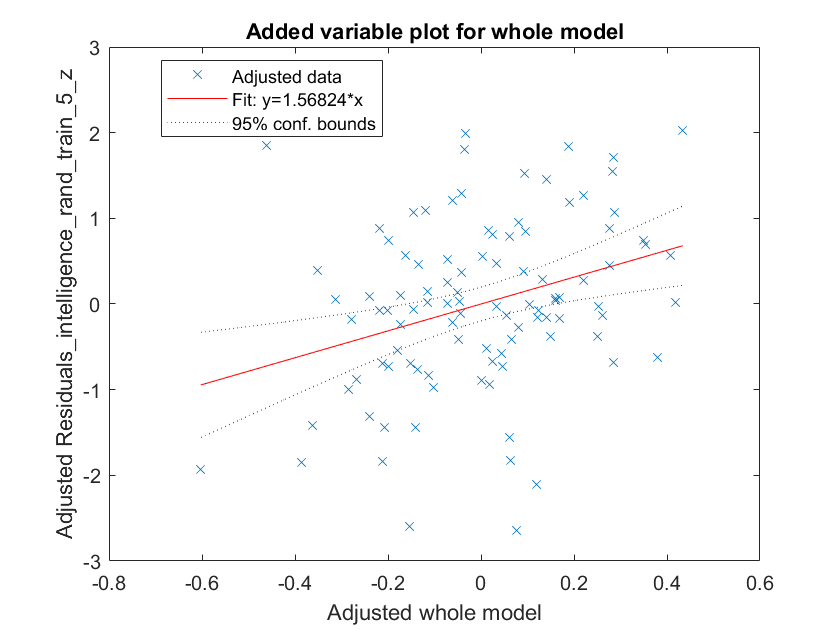

Model_Matrix = [residuals_wm_pos_train_5_z residuals_wm_neg_train_5_z residuals_emo_match_pos_train_5_z residuals_emo_match_neg_train_5_z residuals_stop_signal_pos_train_5_z residuals_stop_signal_neg_train_5_z residuals_intelligence_train_5_rand_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_wm_pos_train_5_z', 'residuals_wm_neg_train_5_z', 'residuals_emo_match_pos_train_5_z', 'residuals_emo_match_neg_train_5_z', 'residuals_stop_signal_pos_train_5_z', 'residuals_stop_signal_neg_train_5_z', 'Residuals_intelligence_rand_train_5_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2) Predict the intelligence scores in the test samples**

1.1. Test Sample 1 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_1 Gender_test_1 meanFDJenk_wm_test_1 meanFDJenk_emo_match_test_1 meanFDJenk_stop_signal_test_1 LQ_test_1];
intelligence_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

residuals_intelligence_test_1 = (Intelligence_test_1 - intelligence_pred_test_1);
residuals_intelligence_test_1_z = normalize(residuals_intelligence_test_1,"center",c_intelligence_train_1,"scale",s_intelligence_train_1);

Retrieve NMA s

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{1,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{1,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{1,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{1,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{1,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{1,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_1 Gender_test_1 meanFDJenk_wm_test_1 meanFDJenk_emo_match_test_1 meanFDJenk_stop_signal_test_1 LQ_test_1];


Positive_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_pos_bcs,confounds);

residuals_pos_wm_test_1 = (Positive_all_wm - Positive_all_pred_wm_test_1);
residuals_pos_wm_test_1_z = normalize(residuals_pos_wm_test_1,"center",c_pos_NMA_wm_train_1,"scale",s_pos_NMA_wm_train_1);

Negative_all_pred_wm_test_1 = predict(mdl_regress_train_1_wm_neg_bcs,confounds);

residuals_neg_wm_test_1 = (Negative_all_wm - Negative_all_pred_wm_test_1);
residuals_neg_wm_test_1_z = normalize(residuals_neg_wm_test_1,"center",c_neg_NMA_wm_train_1,"scale",s_neg_NMA_wm_train_1);


Positive_all_pred_emo_match_test_1 = predict(mdl_regress_train_1_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_1 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_1);
residuals_pos_emo_match_test_1_z = normalize(residuals_pos_emo_match_test_1,"center",c_pos_NMA_emo_match_train_1,"scale",s_pos_NMA_emo_match_train_1);

Negative_all_pred_emo_match_test_1 = predict(mdl_regress_train_1_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_1 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_1);
residuals_neg_emo_match_test_1_z = normalize(residuals_neg_emo_match_test_1,"center",c_neg_NMA_emo_match_train_1,"scale",s_neg_NMA_emo_match_train_1);


Positive_all_pred_stop_signal_test_1 = predict(mdl_regress_train_1_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_1 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_1);
residuals_pos_stop_signal_test_1_z = normalize(residuals_pos_stop_signal_test_1,"center",c_pos_NMA_stop_signal_train_1,"scale",s_pos_NMA_stop_signal_train_1);

Negative_all_pred_stop_signal_test_1 = predict(mdl_regress_train_1_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_1 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_1);
residuals_neg_stop_signal_test_1_z = normalize(residuals_neg_stop_signal_test_1,"center",c_neg_NMA_stop_signal_train_1,"scale",s_neg_NMA_stop_signal_train_1);

Xnew = [residuals_pos_wm_test_1_z residuals_neg_wm_test_1_z residuals_pos_emo_match_test_1_z residuals_neg_emo_match_test_1_z residuals_pos_stop_signal_test_1_z residuals_neg_stop_signal_test_1_z];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

1.2. Test Sample 2 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_2 Gender_test_2 meanFDJenk_wm_test_2 meanFDJenk_emo_match_test_2 meanFDJenk_stop_signal_test_2 LQ_test_2];
intelligence_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

residuals_intelligence_test_2 = (Intelligence_test_2 - intelligence_pred_test_2);
residuals_intelligence_test_2_z = normalize(residuals_intelligence_test_2,"center",c_intelligence_train_2,"scale",s_intelligence_train_2);

Retrieve NMAs

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{2,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{2,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{2,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{2,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{2,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{2,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_2 Gender_test_2 meanFDJenk_wm_test_2 meanFDJenk_emo_match_test_2 meanFDJenk_stop_signal_test_2 LQ_test_2];


Positive_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_pos_bcs,confounds);

residuals_pos_wm_test_2 = (Positive_all_wm - Positive_all_pred_wm_test_2);
residuals_pos_wm_test_2_z = normalize(residuals_pos_wm_test_2,"center",c_pos_NMA_wm_train_2,"scale",s_pos_NMA_wm_train_2);

Negative_all_pred_wm_test_2 = predict(mdl_regress_train_2_wm_neg_bcs,confounds);

residuals_neg_wm_test_2 = (Negative_all_wm - Negative_all_pred_wm_test_2);
residuals_neg_wm_test_2_z = normalize(residuals_neg_wm_test_2,"center",c_neg_NMA_wm_train_2,"scale",s_neg_NMA_wm_train_2);


Positive_all_pred_emo_match_test_2 = predict(mdl_regress_train_2_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_2 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_2);
residuals_pos_emo_match_test_2_z = normalize(residuals_pos_emo_match_test_2,"center",c_pos_NMA_emo_match_train_2,"scale",s_pos_NMA_emo_match_train_2);

Negative_all_pred_emo_match_test_2 = predict(mdl_regress_train_2_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_2 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_2);
residuals_neg_emo_match_test_2_z = normalize(residuals_neg_emo_match_test_2,"center",c_neg_NMA_emo_match_train_2,"scale",s_neg_NMA_emo_match_train_2);


Positive_all_pred_stop_signal_test_2 = predict(mdl_regress_train_2_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_2 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_2);
residuals_pos_stop_signal_test_2_z = normalize(residuals_pos_stop_signal_test_2,"center",c_pos_NMA_stop_signal_train_2,"scale",s_pos_NMA_stop_signal_train_2);

Negative_all_pred_stop_signal_test_2 = predict(mdl_regress_train_2_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_2 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_2);
residuals_neg_stop_signal_test_2_z = normalize(residuals_neg_stop_signal_test_2,"center",c_neg_NMA_stop_signal_train_2,"scale",s_neg_NMA_stop_signal_train_2);

Xnew = [residuals_pos_wm_test_2_z residuals_neg_wm_test_2_z residuals_pos_emo_match_test_2_z residuals_neg_emo_match_test_2_z residuals_pos_stop_signal_test_2_z residuals_neg_stop_signal_test_2_z];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

1.3. Test Sample 3 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_3 Gender_test_3 meanFDJenk_wm_test_3 meanFDJenk_emo_match_test_3 meanFDJenk_stop_signal_test_3 LQ_test_3];
intelligence_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

residuals_intelligence_test_3 = (Intelligence_test_3 - intelligence_pred_test_3);
residuals_intelligence_test_3_z = normalize(residuals_intelligence_test_3,"center",c_intelligence_train_3,"scale",s_intelligence_train_3);

Retrieve NMAs

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{3,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{3,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{3,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{3,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{3,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{3,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_3 Gender_test_3 meanFDJenk_wm_test_3 meanFDJenk_emo_match_test_3 meanFDJenk_stop_signal_test_3 LQ_test_3];


Positive_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_pos_bcs,confounds);

residuals_pos_wm_test_3 = (Positive_all_wm - Positive_all_pred_wm_test_3);
residuals_pos_wm_test_3_z = normalize(residuals_pos_wm_test_3,"center",c_pos_NMA_wm_train_3,"scale",s_pos_NMA_wm_train_3);

Negative_all_pred_wm_test_3 = predict(mdl_regress_train_3_wm_neg_bcs,confounds);

residuals_neg_wm_test_3 = (Negative_all_wm - Negative_all_pred_wm_test_3);
residuals_neg_wm_test_3_z = normalize(residuals_neg_wm_test_3,"center",c_neg_NMA_wm_train_3,"scale",s_neg_NMA_wm_train_3);


Positive_all_pred_emo_match_test_3 = predict(mdl_regress_train_3_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_3 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_3);
residuals_pos_emo_match_test_3_z = normalize(residuals_pos_emo_match_test_3,"center",c_pos_NMA_emo_match_train_3,"scale",s_pos_NMA_emo_match_train_3);

Negative_all_pred_emo_match_test_3 = predict(mdl_regress_train_3_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_3 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_3);
residuals_neg_emo_match_test_3_z = normalize(residuals_neg_emo_match_test_3,"center",c_neg_NMA_emo_match_train_3,"scale",s_neg_NMA_emo_match_train_3);


Positive_all_pred_stop_signal_test_3 = predict(mdl_regress_train_3_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_3 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_3);
residuals_pos_stop_signal_test_3_z = normalize(residuals_pos_stop_signal_test_3,"center",c_pos_NMA_stop_signal_train_3,"scale",s_pos_NMA_stop_signal_train_3);

Negative_all_pred_stop_signal_test_3 = predict(mdl_regress_train_3_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_3 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_3);
residuals_neg_stop_signal_test_3_z = normalize(residuals_neg_stop_signal_test_3,"center",c_neg_NMA_stop_signal_train_3,"scale",s_neg_NMA_stop_signal_train_3);

Xnew = [residuals_pos_wm_test_3_z residuals_neg_wm_test_3_z residuals_pos_emo_match_test_3_z residuals_neg_emo_match_test_3_z residuals_pos_stop_signal_test_3_z residuals_neg_stop_signal_test_3_z];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);

[r,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

1.4. Test Sample 4 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_4 Gender_test_4 meanFDJenk_wm_test_4 meanFDJenk_emo_match_test_4 meanFDJenk_stop_signal_test_4 LQ_test_4];
intelligence_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

residuals_intelligence_test_4 = (Intelligence_test_4 - intelligence_pred_test_4);
residuals_intelligence_test_4_z = normalize(residuals_intelligence_test_4,"center",c_intelligence_train_4,"scale",s_intelligence_train_4);

Retrieve NMAs

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{4,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{4,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{4,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{4,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{4,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{4,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_4 Gender_test_4 meanFDJenk_wm_test_4 meanFDJenk_emo_match_test_4 meanFDJenk_stop_signal_test_4 LQ_test_4];


Positive_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_pos_bcs,confounds);

residuals_pos_wm_test_4 = (Positive_all_wm - Positive_all_pred_wm_test_4);
residuals_pos_wm_test_4_z = normalize(residuals_pos_wm_test_4,"center",c_pos_NMA_wm_train_4,"scale",s_pos_NMA_wm_train_4);

Negative_all_pred_wm_test_4 = predict(mdl_regress_train_4_wm_neg_bcs,confounds);

residuals_neg_wm_test_4 = (Negative_all_wm - Negative_all_pred_wm_test_4);
residuals_neg_wm_test_4_z = normalize(residuals_neg_wm_test_4,"center",c_neg_NMA_wm_train_4,"scale",s_neg_NMA_wm_train_4);


Positive_all_pred_emo_match_test_4 = predict(mdl_regress_train_4_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_4 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_4);
residuals_pos_emo_match_test_4_z = normalize(residuals_pos_emo_match_test_4,"center",c_pos_NMA_emo_match_train_4,"scale",s_pos_NMA_emo_match_train_4);

Negative_all_pred_emo_match_test_4 = predict(mdl_regress_train_4_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_4 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_4);
residuals_neg_emo_match_test_4_z = normalize(residuals_neg_emo_match_test_4,"center",c_neg_NMA_emo_match_train_4,"scale",s_neg_NMA_emo_match_train_4);


Positive_all_pred_stop_signal_test_4 = predict(mdl_regress_train_4_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_4 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_4);
residuals_pos_stop_signal_test_4_z = normalize(residuals_pos_stop_signal_test_4,"center",c_pos_NMA_stop_signal_train_4,"scale",s_pos_NMA_stop_signal_train_4);

Negative_all_pred_stop_signal_test_4 = predict(mdl_regress_train_4_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_4 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_4);
residuals_neg_stop_signal_test_4_z = normalize(residuals_neg_stop_signal_test_4,"center",c_neg_NMA_stop_signal_train_4,"scale",s_neg_NMA_stop_signal_train_4);

Xnew = [residuals_pos_wm_test_4_z residuals_neg_wm_test_4_z residuals_pos_emo_match_test_4_z residuals_neg_emo_match_test_4_z residuals_pos_stop_signal_test_4_z residuals_neg_stop_signal_test_4_z];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);

[r,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

1.5. Test Sample 5 

Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [Age_test_5 Gender_test_5 meanFDJenk_wm_test_5 meanFDJenk_emo_match_test_5 meanFDJenk_stop_signal_test_5 LQ_test_5];
intelligence_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

residuals_intelligence_test_5 = (Intelligence_test_5 - intelligence_pred_test_5);
residuals_intelligence_test_5_z = normalize(residuals_intelligence_test_5,"center",c_intelligence_train_5,"scale",s_intelligence_train_5);

Retrieve NMAs

Best_case_scenario_r_values_pos_wm = Best_case_scenario_test_samples_wm{5,1};
Best_case_scenario_r_values_neg_wm = Best_case_scenario_test_samples_wm{5,2};

Best_case_scenario_r_values_pos_emo_match = Best_case_scenario_test_samples_emo_match{5,1};
Best_case_scenario_r_values_neg_emo_match = Best_case_scenario_test_samples_emo_match{5,2};

Best_case_scenario_r_values_pos_stop_signal = Best_case_scenario_test_samples_stop_signal{5,1};
Best_case_scenario_r_values_neg_stop_signal = Best_case_scenario_test_samples_stop_signal{5,2};

Take the mean per subject

Positive_all_wm = nanmean(Best_case_scenario_r_values_pos_wm,2);
Negative_all_wm = nanmean(Best_case_scenario_r_values_neg_wm,2);

Positive_all_emo_match = nanmean(Best_case_scenario_r_values_pos_emo_match,2);
Negative_all_emo_match = nanmean(Best_case_scenario_r_values_neg_emo_match,2);

Positive_all_stop_signal = nanmean(Best_case_scenario_r_values_pos_stop_signal,2);
Negative_all_stop_signal = nanmean(Best_case_scenario_r_values_neg_stop_signal,2);

Regress out the confounding variables 

confounds = [Age_test_5 Gender_test_5 meanFDJenk_wm_test_5 meanFDJenk_emo_match_test_5 meanFDJenk_stop_signal_test_5 LQ_test_5];


Positive_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_pos_bcs,confounds);

residuals_pos_wm_test_5 = (Positive_all_wm - Positive_all_pred_wm_test_5);
residuals_pos_wm_test_5_z = normalize(residuals_pos_wm_test_5,"center",c_pos_NMA_wm_train_5,"scale",s_pos_NMA_wm_train_5);

Negative_all_pred_wm_test_5 = predict(mdl_regress_train_5_wm_neg_bcs,confounds);

residuals_neg_wm_test_5 = (Negative_all_wm - Negative_all_pred_wm_test_5);
residuals_neg_wm_test_5_z = normalize(residuals_neg_wm_test_5,"center",c_neg_NMA_wm_train_5,"scale",s_neg_NMA_wm_train_5);


Positive_all_pred_emo_match_test_5 = predict(mdl_regress_train_5_emo_match_pos_bcs,confounds);

residuals_pos_emo_match_test_5 = (Positive_all_emo_match - Positive_all_pred_emo_match_test_5);
residuals_pos_emo_match_test_5_z = normalize(residuals_pos_emo_match_test_5,"center",c_pos_NMA_emo_match_train_5,"scale",s_pos_NMA_emo_match_train_5);

Negative_all_pred_emo_match_test_5 = predict(mdl_regress_train_5_emo_match_neg_bcs,confounds);

residuals_neg_emo_match_test_5 = (Negative_all_emo_match - Negative_all_pred_emo_match_test_5);
residuals_neg_emo_match_test_5_z = normalize(residuals_neg_emo_match_test_5,"center",c_neg_NMA_emo_match_train_5,"scale",s_neg_NMA_emo_match_train_5);


Positive_all_pred_stop_signal_test_5 = predict(mdl_regress_train_5_stop_signal_pos_bcs,confounds);

residuals_pos_stop_signal_test_5 = (Positive_all_stop_signal - Positive_all_pred_stop_signal_test_5);
residuals_pos_stop_signal_test_5_z = normalize(residuals_pos_stop_signal_test_5,"center",c_pos_NMA_stop_signal_train_5,"scale",s_pos_NMA_stop_signal_train_5);

Negative_all_pred_stop_signal_test_5 = predict(mdl_regress_train_5_stop_signal_neg_bcs,confounds);

residuals_neg_stop_signal_test_5 = (Negative_all_stop_signal - Negative_all_pred_stop_signal_test_5);
residuals_neg_stop_signal_test_5_z = normalize(residuals_neg_stop_signal_test_5,"center",c_neg_NMA_stop_signal_train_5,"scale",s_neg_NMA_stop_signal_train_5);

Xnew = [residuals_pos_wm_test_5_z residuals_neg_wm_test_5_z residuals_pos_emo_match_test_5_z residuals_neg_emo_match_test_5_z residuals_pos_stop_signal_test_5_z residuals_neg_stop_signal_test_5_z];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3.  Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_rand; ypred2_rand; ypred3_rand; ypred4_rand; ypred5_rand];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho_final,pval_final] = corr(predicted_scores,actual_scores);

**4. Save rho_final & pval_final for permutation test **

Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = rho_final;
Permutation_test_all_cross_val_rounds_pval{cross_validation_round, permutation_test_round} = pval_final;

End permutation test

end

end

**4. Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_AOMIC_PIOP2(:,1))

all_rhos_final_correlations =    -0.1498
   -0.2329
   -0.2301
    0.0085
   -0.0982
   -0.1738
   -0.0873
   -0.0679
   -0.1670
   -0.2402



all_rhos_final_correlations_z_scores = atanh(all_rhos_final_correlations);

mean_all_rhos_final_correlations_z_score = mean(all_rhos_final_correlations_z_scores);

mean_all_rhos_final_correlations_final = tanh(mean_all_rhos_final_correlations_z_score)

mean_all_rhos_final_correlations_final = -0.1147



Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho);


find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations_final)

ans =      1
     3
     4
     5
     7
     8
     9
    10
    11
    12
